%이미지 파일, 라벨 저장
top_folder = 'C:\Users\blue\Desktop\mat';
image_files_jpg = dir(fullfile(top_folder, '**', '*.jpg'));
image_files_jpeg = dir(fullfile(top_folder, '**', '*.jpeg'));
image_files = [image_files_jpg; image_files_jpeg];
bounding_boxes_files = dir(fullfile(top_folder, '**', '*.txt'));

%순서가 섞이지 않도록 다시 정렬
[~, idx_image] = sort({image_files.name});
[~, idx_bbox] = sort({bounding_boxes_files.name});
image_files = image_files(idx_image);
bounding_boxes_files = bounding_boxes_files(idx_bbox);

n = length(image_files);
imageFilename = cell(n, 1);
label = cell(n, 1);
boundingBox = cell(n, 1);


for i = 1:n
    % 이미지 파일명 저장
    imageFilename{i} = fullfile(image_files(i).folder, image_files(i).name);
    
    % 바운딩 박스 데이터 추출
    bbox_path = fullfile(bounding_boxes_files(i).folder, bounding_boxes_files(i).name);
    
    % 텍스트 파일을 읽고 각 줄을 하나의 셀에 저장
    fileID = fopen(bbox_path, 'r');
    tmp_data = textscan(fileID, '%f %f %f %f');
    fclose(fileID);
    
    % 읽어온 데이터를 숫자로 변환하여 바운딩 박스에 저장
    bbox_data = [tmp_data{1}+1 tmp_data{2} tmp_data{3} tmp_data{4}];

    % 모든 바운딩 박스를 저장할 배열에 추가
    boundingBox{i} = bbox_data;

end



T = table(imageFilename, boundingBox);

disp(T)

                                 imageFilename                                       boundingBox     
    ________________________________________________________________________    _____________________

    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210917_0000516373.jpg'}    {[   4 750 4609 989]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210917_0000516388.jpg'}    {[ 13 741 4590 1048]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531481.jpg'}    {[ 19 788 4604 1028]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531492.jpg'}    {[   8 794 4582 982]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531507.jpg'}    {[  7 733 4592 1005]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531508.jpg'}    {[  8 807 4611 1005]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531513.jpg'}    {[  8 794 4611 1022]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531515.jpg'}    {

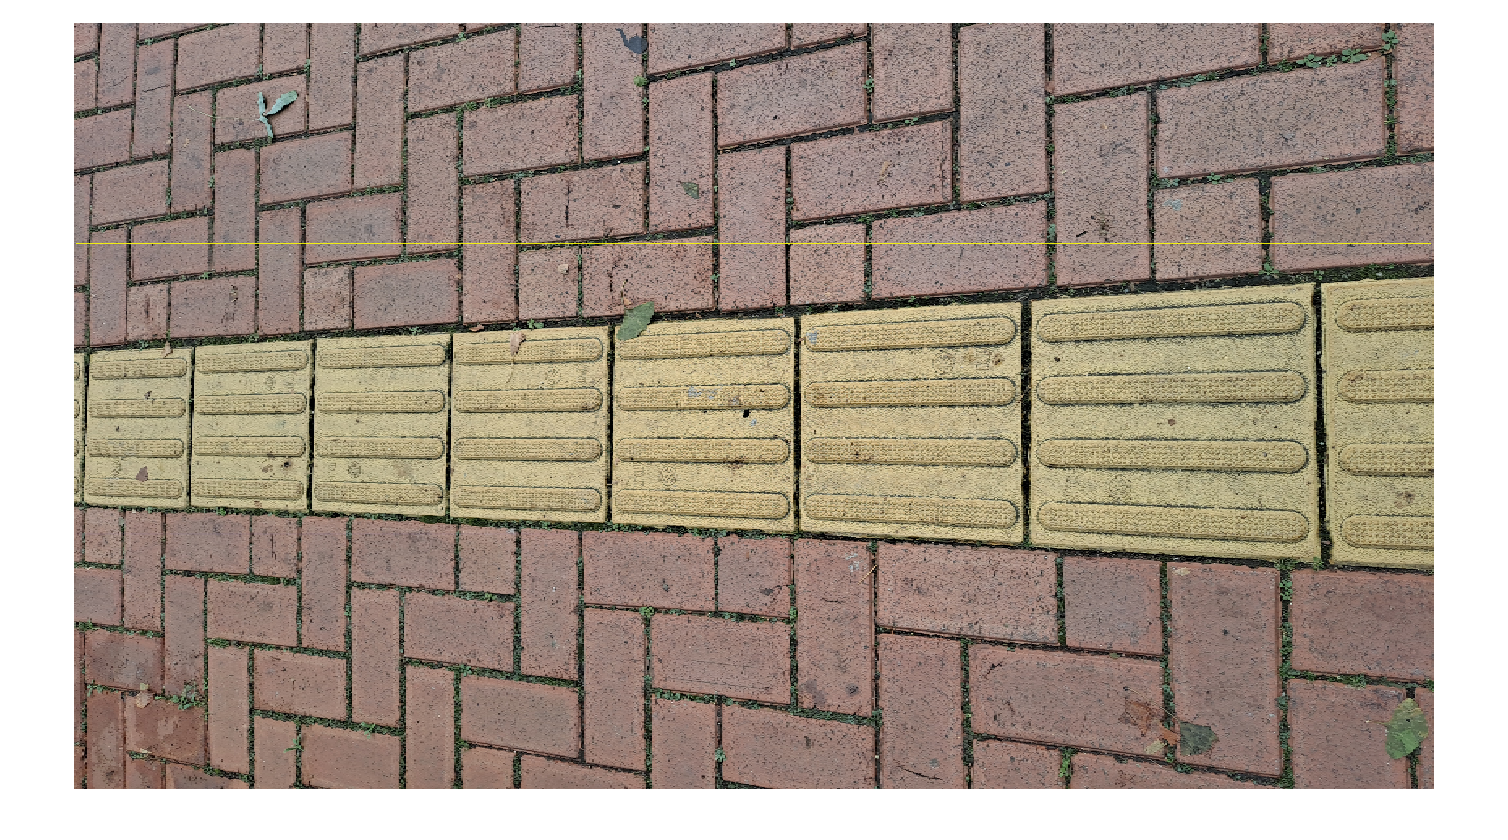

data = imread('C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210917_0000516388.jpg');
bbox = T.boundingBox{1};
annotatedImage = insertShape(data,"Rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
imshow(annotatedImage)

disp(T.imageFilename{1})

C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210917_0000516373.jpg


disp(T)

                                 imageFilename                                       boundingBox     
    ________________________________________________________________________    _____________________

    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210917_0000516373.jpg'}    {[   4 750 4609 989]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210917_0000516388.jpg'}    {[ 13 741 4590 1048]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531481.jpg'}    {[ 19 788 4604 1028]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531492.jpg'}    {[   8 794 4582 982]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531507.jpg'}    {[  7 733 4592 1005]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531508.jpg'}    {[  8 807 4611 1005]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531513.jpg'}    {[  8 794 4611 1022]}
    {'C:\Users\blue\Desktop\mat\VS2\0\2_09_0_1_4_1_20210923_0000531515.jpg'}    {

function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(ii,1:2) = {I,bboxes};
end
end
%data_resized = preprocessData(data, [640, 640, 3]);